% ESE 4481 Aerial Vehicle Homework3: Edgar Sarceno

%_________________________________________________%


## Problem 5 Frames

**Question Requirements**: 

Rewrite (5.2) in a frame that rotates relative to the Earth frame , the body frame. 

Estimate its moment of inertia matrix and state the assumptions used in the calculations. 

**Equation used for inertia**: 

This equation is used to calculate the moment of inertia of some 3D rectangular box with similar dimensions as the drone (equations are in matrix form). Source, Google. 

I_xx = 1/12 * m  * (y^2 + z^2) 

I_yy = 1/12 * m * (x^2 + z^2) 

I_zz = 1/12 * m * (x^2 + y^2) 

Where the moment of inertia for this object, I, is 

I = [I_x, 0, 0;

      0, I_y , 0; 

      0, 0, I_z] ;

**General Outline for Solution**: 

- Calculate the moment in the body frame.

- calculate the angular momentum in the body frame using moment of inertia.

- calculate the angular acceleration in the body frame.

**Code Solution for Prolem 1**:

disp('________________________________________________________________________')

________________________________________________________________________


% Implementing this into our problem: 

% Define symbolic variables
syms p q r real % Angular velocities in body frame

% Define the angular velocity in body axis components
w_b_e = [p; q; r];

% Define the skew-symmetric matrix from the angular velocity vector
S_w = [0, -r, q;
       r, 0, -p;
       -q, p, 0];

% Define symbolic variables for the moments in the earth frame
syms L M N real

% Define the moment in the earth frame
M_earth = [L; M; N];

% Calculate the moment in the body frame
M_body = M_earth + S_w * w_b_e;

% Display the moment in the body frame
disp('Moment in Body Frame, M_body:');

Moment in Body Frame, M_body:


disp(M_body);

$$\left(\begin{array}{c} L\\ M\\ N \end{array}\right)$$


% Define the mass of the UAV
m = 0.042; % kg // First TIme mass is defined 

% Define the dimensions of the UAV (3D square box) using temporary
% variables 'a' , 'b', 'c'.
a = 0.11; % m
b = 0.11; % m
c = 0.029; % m

% Calculate the moment of inertia matrix I
Ixx = (1/12) * m * (b^2 + c^2);
Iyy = (1/12) * m * (a^2 + c^2);
Izz = (1/12) * m * (a^2 + b^2);

% Construct the moment of inertia matrix I
I = [Ixx, 0, 0;
     0, Iyy, 0;
     0, 0, Izz];

% Define the angular momentum of UAV, H:
H = I * w_b_e;

% Calculate the cross product of omega_b/e and I * omega_b/e
cross_product_term = cross(w_b_e, I * w_b_e);

% Solve for dot_omega_b/e
dot_omega_b_e = I \ (M_body - cross_product_term); % \ is used for matrix division which is equivalent to multiplying by the inverse

% Define the number of decimal places you want to round to
decimal_places = 4; 

% Convert to numeric and round off, easier to read format 
dot_omega_b_e_numeric = vpa(dot_omega_b_e, decimal_places); 

% Convert Angular Momentum H to numeric and round off, easier to read
% format. 
H_numeric = vpa(H, decimal_places);

% Display the result
disp('Angular Acceleration in Body Frame, dot_omega_b/e:');

Angular Acceleration in Body Frame, dot_omega_b/e:


disp(dot_omega_b_e_numeric);

$$\left(\begin{array}{c} 22080.0\,L-0.87\,q\,r\\ 22080.0\,M+0.87\,p\,r\\ 11810.0\,N \end{array}\right)$$


disp('Angular Momentum of UAV, H:');

Angular Momentum of UAV, H:


disp(H_numeric);

$$\left(\begin{array}{c} 4.529e-5\,p\\ 4.529e-5\,q\\ 8.47e-5\,r \end{array}\right)$$


%_________________________________________________%

## Problem 6 Rotational Kinematics

**Question Requirements**:

 Find the Singularities in this equation. 

**First Implementation**:

- Construct Matrix H(Capital_Theta), the transformation matrix.

- Determine the determinant of H(Capital_Theta). 

- Solve the equation where the determinant of H(Capital_Theta) equals zero to find singularities. 

- Evaluate and Display Singular Matrices         

**Code for First Implementation**:     

disp('________________________________________________________________________')

________________________________________________________________________


% Define symbolic variables for roll, pitch, and yaw angles
syms phi theta psi real

% Define the matrix H(Theta) as given in the problem
H_theta = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
          0, cos(phi), -sin(phi);
          0, sin(phi)/cos(theta), cos(phi)/cos(theta)];

% Find the determinant of H(Theta)
det_H_theta = det(H_theta);

% Solve the determinant equation det(H_theta) = 0 for theta
singularities_theta = solve(det_H_theta == 0, theta);

% Display the singularities of theta
disp('Singularities of Theta are at:');

Singularities of Theta are at:


disp(singularities_theta);


% Evaluate and Display H(Theta) at the found singularities
for i = 1:length(singularities_theta)
    singular_matrix_postitive = subs(H_theta, theta, singularities_theta(i));
    singular_matrix_negative = subs(H_theta, theta, -singularities_theta(i)); 
    disp(['H(Theta) is singular at theta = ', char(singularities_theta(i)), ':']);
    disp(singular_matrix_positive);
    disp(singular_matrix_negative);
end

**Explanation**: 

There is an absence of explicit solutions from the symbolic solver code above. This is consitent with the known fact that the singularities occur at theta equal to plus or minus pi over two. At these points, the tangent function in the determinnant becomes underfines, or in other words, goes to infinity. This makes the matrix H(theta) non-invertable, or singular. This is further demonstrated with the code below, where the singularity points are explicitly substituted into the calculation. This code is the second implementation of demonstrating the solution to this problem. 

**Second Implementation**: 

- Construct Matrix H(Capital_Theta), the transformation matrix.

- Define Singular points explicitly of where the determinant is zero. 

- Compute the determinant of teh transformation matrix at the identified points. 

- Interpret results.  

**Code for Second Implementation**:  

% Define symbolic variables for roll, pitch, and yaw angles
syms phi theta psi real

% Define the matrix H(Theta) as given in the problem
H_theta = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
          0, cos(phi), -sin(phi);
          0, sin(phi)/cos(theta), cos(phi)/cos(theta)];

% Check the determinant of H(Theta) at theta = pi/2 and theta = -pi/2
%{
det_pos = det(subs(H_theta, theta, pi/2));
det_neg = det(subs(H_theta, theta, -pi/2));

% Display the determinants at the singular points
disp('Determinant of H(Theta) at theta = pi/2:');
disp(det_pos);

disp('Determinant of H(Theta) at theta = -pi/2:');
disp(det_neg);

% If determinant is zero, then display the singular matrices
if det_pos == 0
    disp('H(Theta) is singular at theta = pi/2:');
    disp(subs(H_theta, theta, pi/2));
end

if det_neg == 0
    disp('H(Theta) is singular at theta = -pi/2:');
    disp(subs(H_theta, theta, -pi/2));
end
%}

**Further Explanation:**

This code will not run because line ' det_pos = det(subs(H_theta, theta, pi/2));' implementation tries to divide by zero. Meaning that when the singularity points are substituted in, the function 'blows up.' Making it non-invertable, demonstrating that these are the correct singularity points. 

## Problem 7 Model Gravity

**Question Requirements**: 

Transform the gravity vector from the earth frame to the body frame. 

write out the gravity vector in body coordinates as a funciton of psi (ϕ) and theta (θ). 

Explain why the gravity vector resolved in body coordinates does not depend on the yaw angle. 

**General Outline for Solution**: 

- Define the Grvaity vector in the Earth Frame. 

- Define rotational matrix from earth grame to body frame using psi and theta. 

- Transform the gravity vector to the body frame 

**Code Solution for Prolem 7**:  

disp('________________________________________________________________________')

________________________________________________________________________


% Define symbolic variables for roll, pitch, and yaw angles
syms phi theta psi real

% Define the gravitational acceleration
g = 9.81; % m/s^2, acceleration due to gravity

% Define the gravity vector in the Earth frame
F_g_E = [0; 0; m*g]; % Gravity acts in the positive z direction of the Earth frame

% Define the rotation matrices for roll, pitch, and yaw

% Rotation matrix about x-axis (roll)
R_x = [1, 0, 0;...
       0, cos(phi), sin(phi);...
       0, -sin(phi), cos(phi)]; 

% Rotation matrix about y-axis (pitch)
R_y = [cos(theta), 0, -sin(theta);
       0, 1, 0;
       sin(theta), 0, cos(theta)]; 

% Rotation matrix about z-axis (yaw)
%{ 
Wrong Implementation
R_z = [cos(psi), -sin(psi), 0;
       sin(psi), cos(psi), 0;
       0, 0, 1]; 
%} 
% Rotation matrix about z-axis (yaw)
% Correct Implementation 
R_z = [1, 0, 0;...
       0, 1, 0;...
       0, 0, 1]; 

% Construct the total rotation matrix from Earth frame to Body frame
R_E_B = R_z * R_y * R_x; 

% Transform the gravity vector from Earth frame to Body frame
F_g_B = R_E_B * F_g_E; 

% Display the gravity vector in the Body frame
disp('Gravity Vector in Body Frame, F_g_B:');

Gravity Vector in Body Frame, F_g_B:


disp(F_g_B);

$$\left(\begin{array}{c} -\frac{20601\,\cos\left(\varphi \right)\,\sin\left(\theta \right)}{50000}\\ \frac{20601\,\sin\left(\varphi \right)}{50000}\\ \frac{20601\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{50000} \end{array}\right)$$

**Explanation**:

The yaw angle represents a rotation about the z-axis. This is aligned with the direction of gravity, as depicted in the code based on the information given in the assignment. Gavity in this case acts in the vectical direction and the yaw rotation is a rotation in the horizontal plane around the vertical axis. This means that the yaw rotation does not influence the representation of the gravity vector in the body frame because the gravity is acting along the same axis of the yaw rotation. In the code, the yaw component of the rotation matrix represented by R_z does not affect the z-component of the gravity vector. In other words, when you multiply the rotation matrix R_E_B with F_g_E, it leaves the z-component unchanged. Further emphasizing that the yaw angle does not influence the z-component of the gravity vector in the body frame. 

## Problem 8 Propulsive Motor Force and Moments

**Problem Requirements**: 

Estimate the propeler's thrust coefficient. Assume sea level air density. 

**General Outline For Solution**:    

- Create a data set based on values given on the problem pdf. 

- Then converted each data value to appropriate unit.

- Defined a matrix variable. First column the set of thurst values. Second column is Capital Phi(n) calculated values usign given equaiton. 

- Create a data set of y (Thrust) predictions using the calculated Capital Phi as a funciton of n. 

- Ploted both data sets to verify answer. 

disp('________________________________________________________________________')

________________________________________________________________________


% 8(1)
% Define the variable data_set_initial_values to store the initial values from the data table
% Each row corresponds to a data point, where:
% - The first column is the value of thrust (in grams)
% - The second column is the value of RPM (not converted)

data_set_initial_values = [0.0, 0;    % Row 1: Thrust = 0.0g, RPM = 0.
                           1.6, 4485; % Row 2: Thrust = 1.6g, RPM = 4485.
                           4.8, 7570; % Row 3: Thrust = 4.8g, RPM = 7570.
                           7.9, 9374; % Row 4: Thrust = 7.9g, RPM = 9374.
                           10.9, 10885; % Row 5: Thrust = 10.9g, RPM = 10885.
                           13.9, 12277; % Row 6: Thrust = 13.9g, RPM = 12277.
                           17.3, 13522; % Row 7: Thrust = 17.3g, RPM = 13522.
                           21.0, 14681; % Row 8: Thrust = 21.0g, RPM = 24691.
                           24.4, 15924; % Row 9: Thrust = 24.4g, RPM = 15924.
                           28.6, 17174; % Row 10: Thrust = 28.6g, RPM = 17174.
                           32.8, 18179; % Row 11: Thrust = 32.8g, RPM = 18179.
                           37.3, 19397; % Row 12: Thrust = 37.3g, RPM = 19397.
                           41.7, 20539; % Row 13: Thrust = 41.7g, RPM = 20539.
                           46.0, 21692; % Row 14: Thrust = 46.0g, RPM = 21692.
                           51.9, 22598;]; % Row 15: Thrust = 51.9g, RPM = 22598.

% Display the intial values data set from the provided data table
disp('Initial Data Set before conversion:');

Initial Data Set before conversion:


disp(data_set_initial_values); 

   1.0e+04 *

         0         0
    0.0002    0.4485
    0.0005    0.7570
    0.0008    0.9374
    0.0011    1.0885
    0.0014    1.2277
    0.0017    1.3522
    0.0021    1.4681
    0.0024    1.5924
    0.0029    1.7174
    0.0033    1.8179
    0.0037    1.9397
    0.0042    2.0539
    0.0046    2.1692
    0.0052    2.2598




% Extract the first column (Thrust in g) and convert to kg
Thrust_newtons = ( data_set_initial_values(:, 1) / 1000 ) * 9.8; % 1 g = 0.001 kg, converting to a force by * by 9.8 

% Extract the second column (Speed in RPM) and convert to Hz
Speed_hz = data_set_initial_values(:, 2) / 60; % 1 RPM = 1/60 Hz


% Display the converted data set
disp('Converted Data Set:');

Converted Data Set:


disp('Thurst (N): '); 

Thurst (N): 


disp([Thrust_newtons]);

         0
    0.0157
    0.0470
    0.0774
    0.1068
    0.1362
    0.1695
    0.2058
    0.2391
    0.2803
    0.3214
    0.3655
    0.4087
    0.4508
    0.5086



disp('Speed (Hz): ');

Speed (Hz): 


disp([Speed_hz]);

         0
   74.7500
  126.1667
  156.2333
  181.4167
  204.6167
  225.3667
  244.6833
  265.4000
  286.2333
  302.9833
  323.2833
  342.3167
  361.5333
  376.6333





% Calculating the data set for thrust and capital_phi to plot
% Equation used: T = p_row * 4 * D^5 * n^2 * C_t 

% Define constants
p_row = 1.225; % Density of air in kg/m^3
D = 0.045; % Prop diameter in m, converted from 45 mm

% Calculate Capital_phi for each data point
Capital_phi = 4 * p_row * D^4 * (Speed_hz.^2);

% Display the data points
disp('Data Points with their corresponding values:');

Data Points with their corresponding values:


disp('Trhust (N), Capital Phi.')

Trhust (N), Capital Phi.


disp([Thrust_newtons, Capital_phi]); % this matrix will be used for least squares. 

         0         0
    0.0157    0.1123
    0.0470    0.3198
    0.0774    0.4904
    0.1068    0.6613
    0.1362    0.8413
    0.1695    1.0205
    0.2058    1.2030
    0.2391    1.4153
    0.2803    1.6462
    0.3214    1.8445
    0.3655    2.1000
    0.4087    2.3545
    0.4508    2.6263
    0.5086    2.8503




% Using least squares method to calculate C_t 

% least_squares = (phi' * phi) \ phi' * y; % Where phi is the regressor and y is the output

% For data_points dataset
% Extracting the regressor (Capital_phi) and output (Thrust) from data_points
phi = Capital_phi; % Regressor
y = Thrust_newtons; % Output

% Calculating the least squares solution for Ct (Coefficient of Thrust)
Ct_least_squares = (phi' * phi) \ phi' * y; % This will give the least squares solution for Ct

% Display the result
disp('Coefficient of Thrust, Ct (Least Squares):');

Coefficient of Thrust, Ct (Least Squares):


disp(Ct_least_squares);

    0.1731



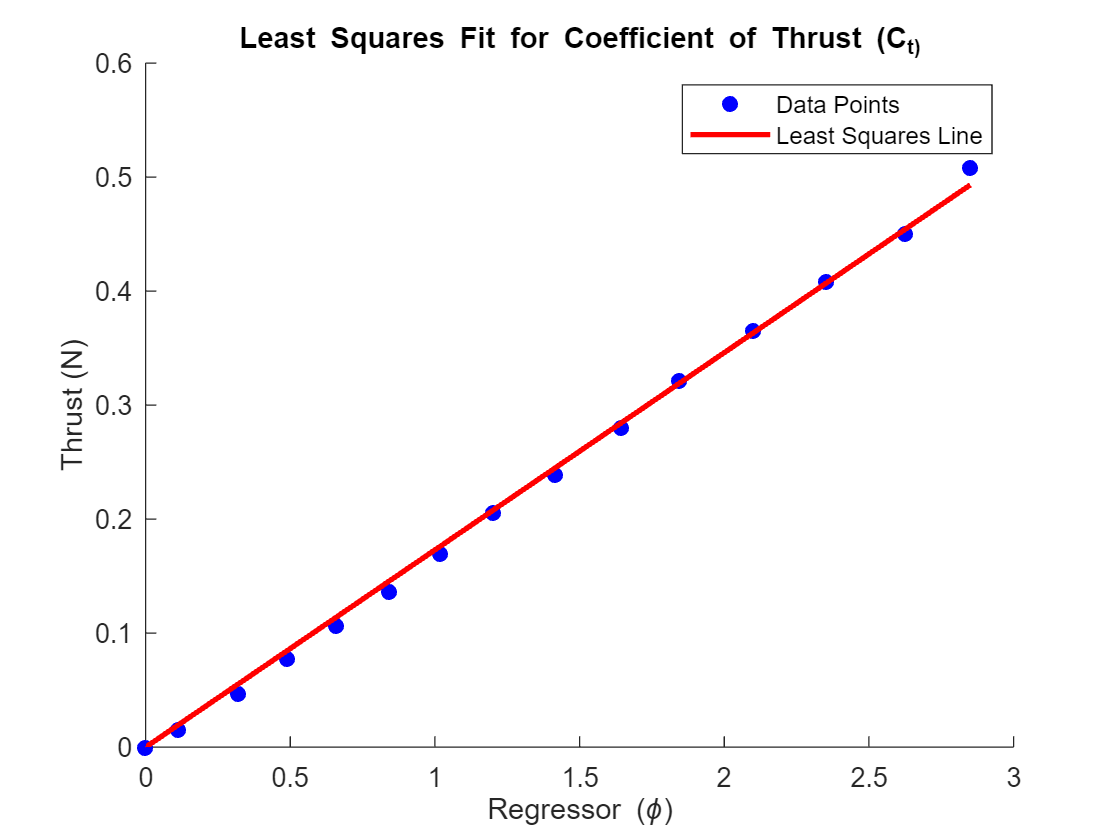


% Calculating the predicted y values using the least squares solution
y_pred = phi * Ct_least_squares; % Prediction for Thrust to verify C_t coefficient 

% Plotting the original data points
figure;
scatter(phi, y, 'b', 'filled'); 
hold on;

% Plotting the least squares line
plot(phi, y_pred, 'r', 'LineWidth', 2);

% Adding title and labels to the plot
title('Least Squares Fit for Coefficient of Thrust (C_t)');
xlabel('Regressor (\phi)'); % Capital_phi
ylabel('Thrust (N)');

% Adding a legend to differentiate between the data points and the least squares line
legend('Data Points', 'Least Squares Line');

% Displaying the plot
hold off;

**Problem Requirements**: 

Estimate the propeller's power coefficient . Assume sea level air density. 

**General Outline For Solution**:

- Create a data set based on values given on the problem pdf. 

- Then converted each data value to appropriate unit.

- Calculate the Capital_phi values using the given equation

- Created a matrix of Power (y outputs) and Capital_phi

- Calculated the power coefficient Cp 

- ploted to verify data. 

disp('________________________________________________________________________')

________________________________________________________________________



% 8(2)
% Define the variable data_set_initial_values to store the initial values from the data table
% Each row corresponds to a data point, where:
% - The first column is the value of amps
% - The second column is the value of voltage.  

power_initial_values = [0.24, 4.01 * 0; % Row 1: Current = 0.24A, Voltage = 4.01V * 0%.
                        0.37, 3.98 * (6.25/100); % Row 2: Current = 0.37A, Voltage = 3.98V * 6.25%.
                        0.56, 3.95 * (12.5/100); % Row 3: Current = 0.56A, Voltage = 3.95V * 12.5%.
                        0.75, 3.92 * (18.75/100); % Row 4: Current = 0.75A, Voltage = 3.92V * 18.75%.
                        0.94, 3.88 * (25/100); % Row 5: Current = 0.94A, Voltage = 3.88V * 25%.
                        1.15, 3.84 * (31.25/100); % Row 6: Current = 1.15A, Voltage = 3.84V * 31.25%.
                        1.37, 3.80 * (37.5/100); % Row 7: Current = 1.37A, Voltage = 3.80V * 37.5%.
                        1.59, 3.76 * (43.25/100); % Row 8: Current = 1.59A, Voltage = 3.76V * 43.25%.
                        1.83, 3.71 * (50/100); % Row 9: Current = 1.83A, Voltage = 3.71V * 50%.
                        2.11, 3.67 * (56.25/100); % Row 10: Current = 2.11A, Voltage = 3.67V * 56.25%.
                        2.39, 3.65 * (62.5/100); % Row 11: Current = 2.39A, Voltage = 3.65V * 62.5%.
                        2.71, 3.62 * (68.75/100); % Row 12: Current = 2.71A, Voltage = 3.62V * 68.75%.
                        3.06, 3.56 * (75/100); % Row 13: Current = 3.06A, Voltage = 3.56V * 75%.
                        3.46, 3.48 * (81.25/100); % Row 14: Current = 3.46A, Voltage = 3.48V * 81.25%.
                        3.88, 3.40 * (87.5/100);]; % Row 15: Current = 3.88A, Voltage = 3.40V * 87.5%.

% Display the initial values data set from the provided data table
disp('Initial Power Data Set: ');

Initial Power Data Set: 


disp(power_initial_values);

    0.2400         0
    0.3700    0.2487
    0.5600    0.4938
    0.7500    0.7350
    0.9400    0.9700
    1.1500    1.2000
    1.3700    1.4250
    1.5900    1.6262
    1.8300    1.8550
    2.1100    2.0644
    2.3900    2.2812
    2.7100    2.4888
    3.0600    2.6700
    3.4600    2.8275
    3.8800    2.9750





% Calculate power for each data point
Current_amps = power_initial_values(:, 1);
Voltage_volts = power_initial_values(:, 2);
Power_watts = Current_amps .* Voltage_volts;

% Display Power in watts. 
disp('Power used for each data point:');

Power used for each data point:


disp(Power_watts);

         0
    0.0920
    0.2765
    0.5513
    0.9118
    1.3800
    1.9522
    2.5857
    3.3946
    4.3558
    5.4522
    6.7445
    8.1702
    9.7832
   11.5430





% Calculating the data set for thrust and capital_phi to plot
% Equation used: P = p_row * 4 * D^5 * n^3 * Cp  = V * I 
%                P = V * I = thrust * w 

% Define constants
p_row = 1.225; % Density of air in kg/m^3
D = 0.045; % Prop diameter in m, converted from 45 mm


% Calculate Capital_phi values using the given equation
Capital_phi_power = 4 * p_row * D^5 * ((Voltage_volts) * 2 * pi).^3; % Convert n from RPM to rad/s

% Calculate the least squares solution for Cp (Power Coefficient)
Cp_least_squares = (Capital_phi_power' * Capital_phi_power) \ Capital_phi_power' * Power_watts;

% Calculating the predicted y values using the least squares solution
Power_predicted = Capital_phi_power * Cp_least_squares;


% Display the calculated Power Coefficient
disp(['The estimated Power Coefficient (C_p) is: ', num2str(Cp_least_squares)]);

The estimated Power Coefficient (C_p) is: 1979.0226


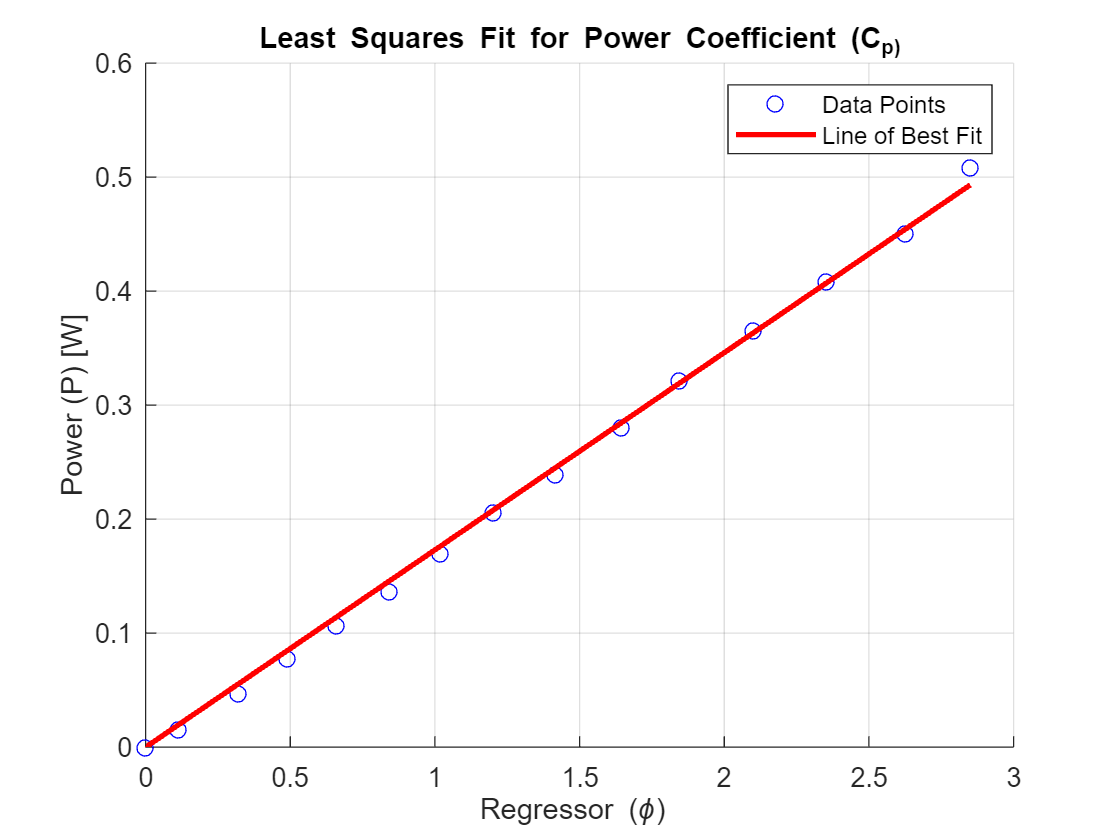


% Plotting the data points and the line of best fit
figure;
scatter(phi, y, 'b'); % Plot the data points in blue
hold on;
plot(phi, y_pred, 'r','LineWidth', 2); % Plot the line of best fit in red
xlabel('Regressor (\phi) ');
ylabel('Power (P) [W]');
title('Least Squares Fit for Power Coefficient (C_p)');
legend('Data Points', 'Line of Best Fit');
grid on;
hold off;

**Problem Requirements**: 

Estimate the propeller’s torque coefficient. Assume sea level air density. 

**General Outline For Solution**:

- Create a data set based on values given on the problem pdf and from the previous two sections. 

- Calculate the torque given the relationships of the equations based on the data values created. 

- Calculate Capital_phi from the equations provided. This will be used in the least squares method.  

- Use the least squares method to calculate the torque coefficient C_m. 

- Create a prediction method of the torque. 

- Plot the data values against each other to verify calculations. 

disp('________________________________________________________________________')

________________________________________________________________________


% 8(3)
% Equations used in this problem: 
% P = Q * w
% Q = Cm * p_row * D^4 * n^2 * 4 , where Q is torque 
% w = 2 * pi * n , where n is motor speed in Hz, and w is angular velocity 

% Estimating the propeller's torque coefficient (C_m) using the least squares method.

% Define constants
p_row = 1.225; % Density of air in kg/m^3 at sea level
D = 0.045; % Prop diameter in m, converted from 45 mm

% Extracting motor speed (n) from 'Thrust_Hz' defined in 8(1)
n_values = Speed_hz;

% Extracting power (P) from 'Power_watts' calculated in 8(2)
P_values = Power_watts; % Power in Watts

% Calculate the torque (Q) for each data point using Q = P / w
% w (angular velocity) is calculated as w = 2 * pi * n

% Set the first row of the first column of torque_data_points to zero to handle the division by zero.
Torque_Nm = zeros(size(n_values));
Torque_Nm(1) = 0; % Torque is zero when n is zero

% Calculate the torque (Q) for each data point from the second row onwards using Q = P / w
Torque_Nm(2:end) = P_values(2:end) ./ (2 * pi * n_values(2:end));

% Calculate the regressor (Phi) values using the given equation
Regressor_phi = 4 * p_row * D^4 * (n_values.^2);


% Calculate the least squares solution for C_m (Torque Coefficient)
Cm_least_squares = (Regressor_phi' * Regressor_phi) \ Regressor_phi' * Torque_Nm;


% Calculating the predicted y values using the least squares solution
Torque_predicted = Regressor_phi * Cm_least_squares;

% Display the calculated Torque Coefficient
disp(['The estimated Torque Coefficient (C_m) is: ', num2str(Cm_least_squares)]);

The estimated Torque Coefficient (C_m) is: 0.0015791


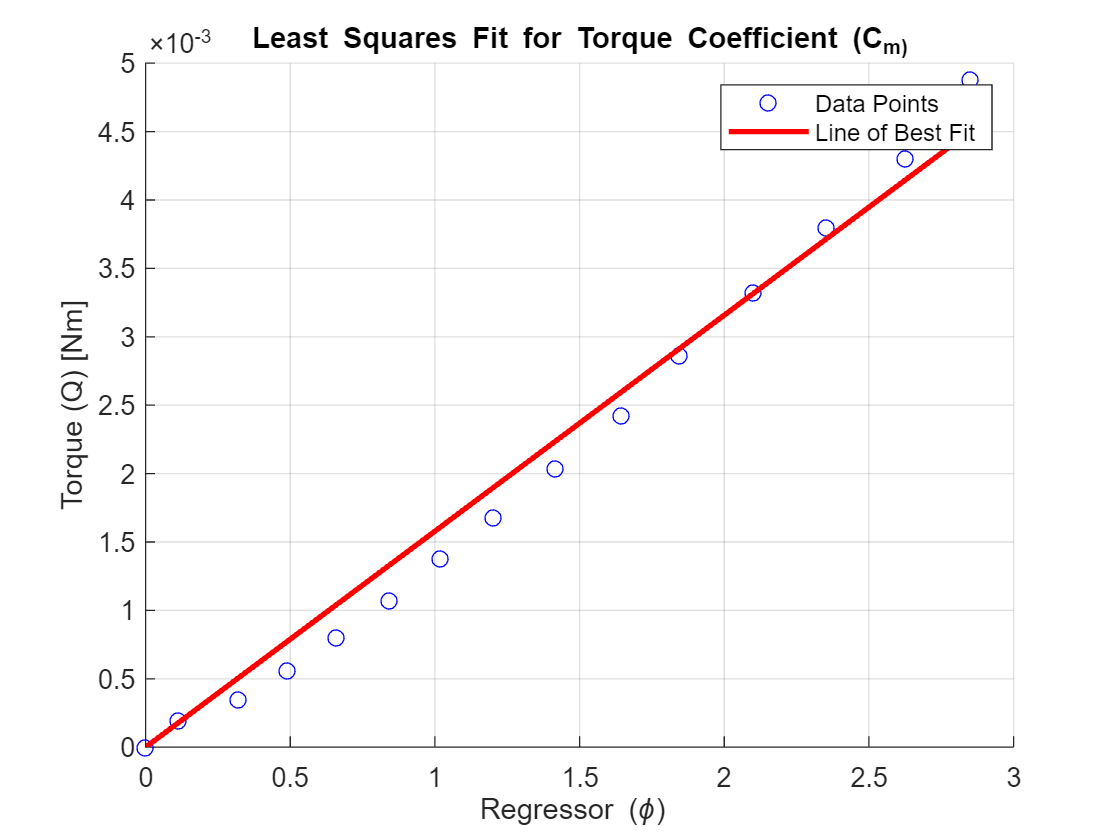


% Plotting the data points and the line of best fit
figure;
scatter(Regressor_phi, Torque_Nm, 'b'); % Plot the data points in blue
hold on;
plot(Regressor_phi, Torque_predicted, 'r', 'LineWidth', 2);%% Plot the line of best fit in red
xlabel('Regressor (\phi) ');
ylabel('Torque (Q) [Nm]');
title('Least Squares Fit for Torque Coefficient (C_m)');
legend('Data Points', 'Line of Best Fit');
grid on;
hold off;

**Problem Requirements**: 

Determine pitching moment produced by each motor as a function of motor speed.

**General Outline For Solution**:

- Calculated the distance between a motor and the center of gravity of the drone. 

- Calculated the pitching moment for each motor speed as a function of n and thrust(n). 

- Plotted data to verify method used. 

disp('________________________________________________________________________')

________________________________________________________________________


% 8(4) 
% Define the distance from the center of mass to the motor (r) in meters
r = (92 / 2) / 1000; % Convert from mm to m

% Assuming Speed_hz is already defined as the array of motor speeds in Hz
% and Thrust_newtons is already defined as the array of thrust values in Newtons

% Calculate the pitching moment for each motor speed
M_pitching_values = r .* Thrust_newtons; % Element-wise multiplication of r and thrust for each motor speed


disp('Pitching Moment for each data point in Newton-meters');

Pitching Moment for each data point in Newton-meters


disp(M_pitching_values);

         0
    0.0007
    0.0022
    0.0036
    0.0049
    0.0063
    0.0078
    0.0095
    0.0110
    0.0129
    0.0148
    0.0168
    0.0188
    0.0207
    0.0234



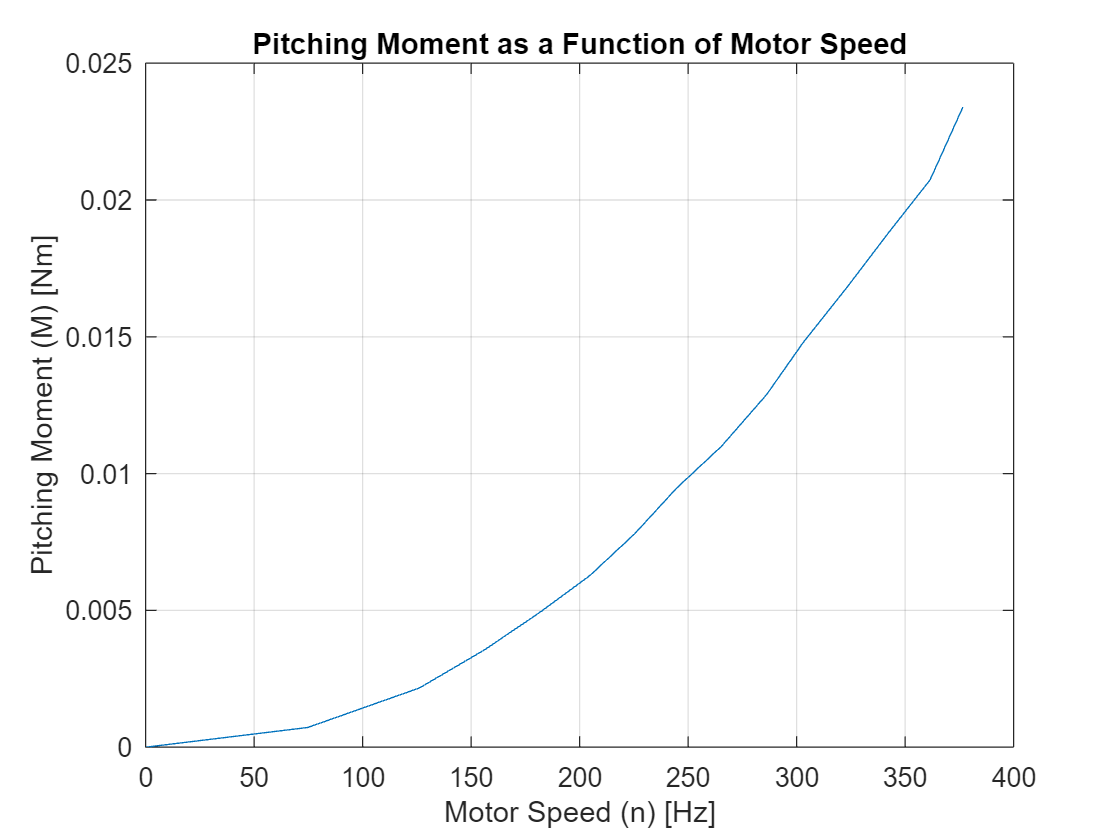


% Plot the pitching moment as a function of motor speed
figure;
plot(Speed_hz, M_pitching_values);
xlabel('Motor Speed (n) [Hz]');
ylabel('Pitching Moment (M) [Nm]');
title('Pitching Moment as a Function of Motor Speed');
grid on;

**Problem Requirements**: 

Determine the rolling moment produced by each motor as a function of motor speed.

**General Outline For Solution**:

- Calculated the distance is the perpendicular distance from the motor to the roll axis. 

- Calculated the pitching moment for each motor speed as a function of n and thrust(n). 

- Plotted data to verify method used

disp('________________________________________________________________________')

________________________________________________________________________


% 8(5)
% Define constants
distance_between_motors_m = 0.092; % 92 mm converted to meters
distance_to_roll_axis_m = distance_between_motors_m *  sqrt(2)/2; % Distance from each motor to the roll axis

% Calculate the rolling moment for each data point
RollingMoment_Nm = Thrust_newtons .* distance_to_roll_axis_m; % Rolling moment in Newton-meters, using element-wise multiplication

% Display the calculated rolling moments
disp('Rolling Moment for each data point in Newton-meters:');

Rolling Moment for each data point in Newton-meters:


disp(RollingMoment_Nm);

         0
    0.0010
    0.0031
    0.0050
    0.0069
    0.0089
    0.0110
    0.0134
    0.0156
    0.0182
    0.0209
    0.0238
    0.0266
    0.0293
    0.0331



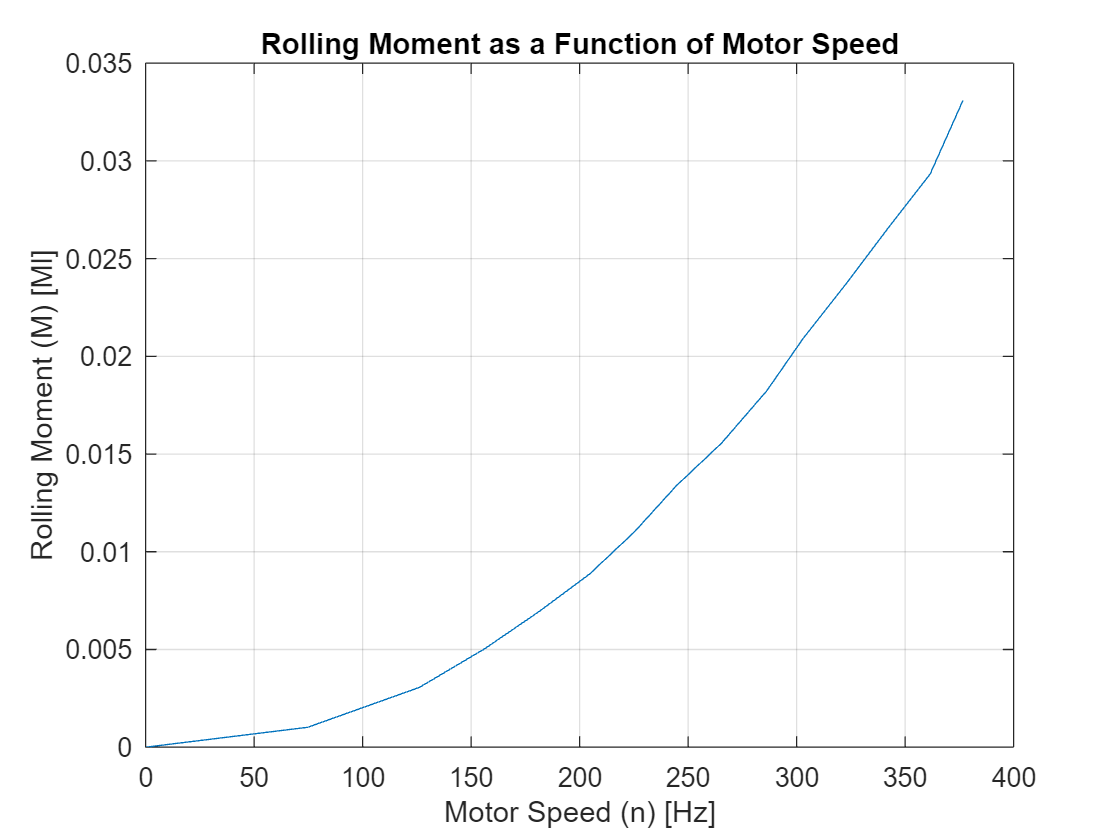


figure; 
plot(Speed_hz, RollingMoment_Nm);
xlabel('Motor Speed (n) [Hz]');
ylabel('Rolling Moment (M) [Ml]'); 
title('Rolling Moment as a Function of Motor Speed'); 
grid on; 

**Problem Requirements**: 

Determine yawing moment produced by each motor as a function of motor speed. 

**General Outline For Solution**:

- Calculated the distance is the perpendicular distance from the motor to the roll axis. 

- Calculated the pitching moment for each motor speed as a function of n and thrust(n). 

- Plotted data to verify method used

disp('________________________________________________________________________')

________________________________________________________________________


% 8(6) 
% Extract power values and motor speeds from the data set
Power_W = Power_watts; % Power in Watts, using the variable name established in 8(2)
Speed_Hz = Speed_hz; % Motor speed in Hz, using the variable name established previously

% Initialize YawingMoment_Nm and Speed_rad_s variables
YawingMoment_Nm = zeros(size(Power_W)); % Initialize with zeros
Speed_rad_s = zeros(size(Power_W)); % Initialize with zeros

% Define the first element of yawing_moment_Nm as zero
YawingMoment_Nm(1) = 0; % As the first element of Speed_hz is zero, leading to division by zero
Speed_rad_s(1) = 0; 

% Convert motor speed from Hz to rad/s for the remaining elements starting from the second row
Speed_rad_s(2:end) = 2 * pi * Speed_Hz(2:end); 

% Calculate the torque for each data point starting from the second row
Torque_Nm = Power_W(2:end) ./ Speed_rad_s(2:end); % Torque in Newton-meters

% Assign the calculated torque values to the YawingMoment_Nm variable starting from the second row
YawingMoment_Nm(2:end) = Torque_Nm; % Yawing moment in Newton-meters

% Display the calculated yawing moments
disp('Yawing Moment for each data point in Newton-meters:');

Yawing Moment for each data point in Newton-meters:


disp(YawingMoment_Nm);

         0
    0.0002
    0.0003
    0.0006
    0.0008
    0.0011
    0.0014
    0.0017
    0.0020
    0.0024
    0.0029
    0.0033
    0.0038
    0.0043
    0.0049



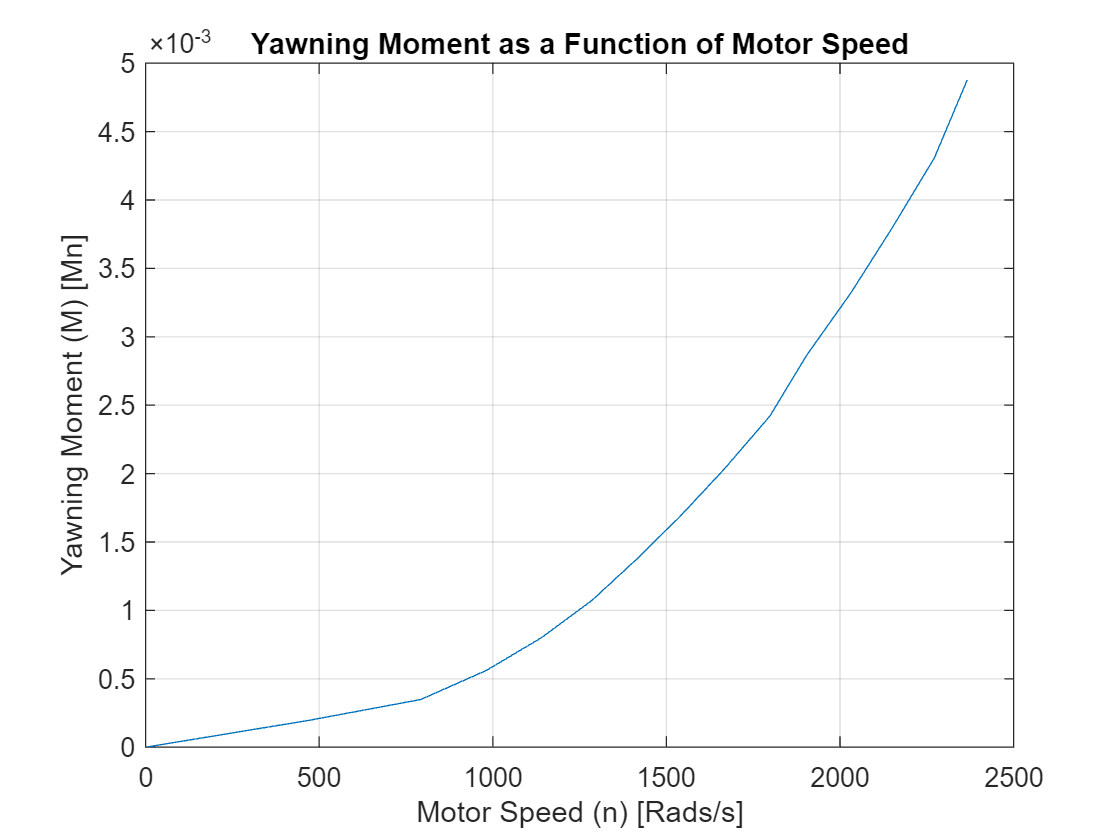


figure; 
plot(Speed_rad_s, YawingMoment_Nm);  
xlabel('Motor Speed (n) [Rads/s]');
ylabel('Yawning Moment (M) [Mn]');
title('Yawning Moment as a Function of Motor Speed'); 
grid on;

**Problem Requirements**: 

Estimate the angular velocity of the four propellers (assuming they all maintain the same constant speed) to produce a thrust equal and opposite to gravity (trim to 1g). 

**General Outline For Solution**:

- Convert the thrust of the individual propeller to 1/4th. 

- Calculate the angular velocity using given equation. 

- Display the results for calculation verification. 

disp('________________________________________________________________________')

________________________________________________________________________


% 8(7)
% Define constants
p_row = 1.225; % Density of air in kg/m^3
D = 0.045; % Prop diameter in m, converted from 45 mm
g = 9.81; % Acceleration due to gravity in m/s^2s

% The total thrust needed to counteract gravity for all four propellers is equal to the gravitational force acting on the drone.
% Since there are four propellers, the thrust produced by each propeller is 1/4th of the total thrust needed.
T_per_propeller_N = g / 4; % Thrust per propeller in Newtons to balance out 1g of gravitational acceleration

% Calculate the angular velocity needed for each propeller to produce the required thrust
n_rad_s = sqrt(T_per_propeller_N / (Ct_least_squares * p_row * D^4)); % Angular velocity in rad/s
Speed_n_Hz = n_rad_s / (2 * pi); % Convert angular velocity to Hz

% Display the calculated angular velocity
disp(['The estimated angular velocity of the four propellers to produce']); 

The estimated angular velocity of the four propellers to produce


disp(['thrust equal and opposite to gravity (1g) is: ', num2str(Speed_n_Hz), ' Hz']);

thrust equal and opposite to gravity (1g) is: 267.3249 Hz


## Problem 9 Translational Kinematics

% Given Information in the probelm

% Velocity of the vehicle in an earth frame 
% v_E = [V_n, V_E, V_D]; 

% Ground Speed of the UAV 
% V_b = [u, v, w]; = R_b_E * V_E

**Problem Requirements**: 

Derive the expression for R_E_B in terms of the euler angles ϕ, θ, and ψ.

**General Outline For Solution**:

- Define the rotational matrix for the euler angles. 

- Computer the roation multiplicaiton calculation.

- Display Results for calculation verification.

% Define symbolic variables for Euler angles
syms phi theta psi real

% Define the Roll rotation matrix
R_phi = [1, 0, 0;
         0, cos(phi), -sin(phi);
         0, sin(phi), cos(phi)];

% Define the Pitch rotation matrix
R_theta = [cos(theta), 0, sin(theta);
           0, 1, 0;
           -sin(theta), 0, cos(theta)];

% Define the Yaw rotation matrix
R_psi = [cos(psi), -sin(psi), 0;
         sin(psi), cos(psi), 0;
         0, 0, 1];

% Compute the combined rotation matrix R_E_B
R_E_B = R_phi * R_theta * R_psi; 

% Display the combined rotation matrix R_E_B
disp('The combined rotation matrix R_E_B is:');

The combined rotation matrix R_E_B is:


disp(R_E_B);

$$\left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\psi \right) & \sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)+\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$


%_____Going Backwards to provide proof of the implementation on top_____% 


% Given the property of orthonormal matrices, the inverse is the transpose
R_B_E_transpose = R_E_B'; % This is the transpose of R_E_B

% Display the matrix R_B_E
disp('The rotation matrix R_B_E (going backwards) is:');

The rotation matrix R_B_E (going backwards) is:


disp(R_B_E_transpose);

$$\left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)-\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ -\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)+\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sin\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$


% Further Proof: 
% Applying the transpose operator to the formula
R_E_B_backwards = R_phi' * R_theta' * R_psi';

% Display the matrix R_E_B_backwards
disp('The matrix R_E_B_backwards is:');

The matrix R_E_B_backwards is:


disp(R_E_B_backwards);

$$\left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & -\sin\left(\theta \right)\\ \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

## Problem 10 The Equation Of Motion

**Requirements of Matrix A**:

The elements of matrix A are the coefficients of the linearized differential equations of motion. Matrix AA encapsulates the inherent dynamics of the UAV, excluding any external control inputs.


% Define symbolic variables
syms phi theta psi p q r F_t u v w pn pe pd nFR nFL nRR nRL My Mx My real 

% Context for variables: 
% p_row = 1.225; % Density of air in kg/m^3 at sea level
% D = 0.045; % Prop diameter in m, converted from 45 mm

% K_p = Cp_least_squares ; % Power Coefficient
% k_t = Ct_least_squares; % Coefficient of Thrust 
% distance_to_roll_axis_m
% K_p = Cp_least_squares ; 

omega = [p; q; r]; % omega_B_E, angular velocity 
v_b = [u; v; w]; 
x = [pn; pe; pd; u; v; w; phi; theta; psi; p; q; r];
V_b = [u; v; w]; % Velocity in body frame 
n_motors = [nFR; nFL; nRR; nRL]; % For B Matrix 

% inertia matrix 
I = [Ixx, 0, 0;
     0, Iyy, 0;
     0, 0, Izz]; 

% inertia matrix inverse 
I_inv = inv(I); 

% Calculate moment
K_p = Cp_least_squares ; % Power Coefficient
k_t = Ct_least_squares; % Coefficient of Thrust 

distance_roll = distance_to_roll_axis_m; 
Distance_to_pitch_axis = distance_to_roll_axis_m; 

% Define the Roll rotation matrix 
% Order of rotation Z, Y, X 
R_phi = [1, 0, 0;
         0, cos(phi), -sin(phi);
         0, -sin(phi), cos(phi)];

% Define the Pitch rotation matrix
R_theta = [cos(theta), 0, -sin(theta);
           0, 1, 0;
           sin(theta), 0, cos(theta)];

% Define the Yaw rotation matrix
R_psi = [cos(psi), sin(psi), 0;
         -sin(psi), cos(psi), 0;
         0, 0, 1];

% Matrix A: 

% Compute the combined rotation matrix R_E_B
R_E_B = R_phi * R_theta * R_psi; 
R_B_E = R_E_B'; % Going backward 

F_g_b = R_E_B' * [0; 0; m*g];  % force of gravity acting on the UAV in the body frame

% Define Moments:
% Mx = Roll Moment, My = Pitch Moment, Mz = Yaw Moment

% Creating Rolling Function 
Rolling_function = @(x) p_row * Ct_least_squares * D^4 * x^2  * distance_to_roll_axis_m; 

% Mx
M_x_FR = -Rolling_function(nFR);
M_x_FL = Rolling_function(nFL);
M_x_RL = Rolling_function(nRL);
M_x_RR = -Rolling_function(nRR);

% My

% Creating Pitching Function
Pitching_function = @(x) p_row * Ct_least_squares * D^4 * x^2  * Distance_to_pitch_axis; 

M_y_FR = Pitching_function(nFR);
M_y_FL = Pitching_function(nFL);
M_y_RL = -Pitching_function(nRL);
M_y_RR = -Pitching_function(nRR);


% Mz 
Yawing_Function = @(x) ((p_row * Cp_least_squares * D^5) / 2 * pi ) * x^2;

M_z_FR = Yawing_Function(nFR);
M_z_FL = -Yawing_Function(nFL);
M_z_RL = Yawing_Function(nRL);
M_z_RR = -Yawing_Function(nRR);
 
Mx = M_x_FR + M_x_FL + M_x_RL + M_x_RR; 
My = M_y_FR + M_y_FL + M_y_RL + M_y_RR;
Mz = M_z_FR + M_z_FL + M_z_RL + M_z_RR;

% Moment Vector
M_t = [ Mx;... 
        My;... 
        Mz;]

$$M\_t = \begin{array}{l} \left(\begin{array}{c} \sigma_{4}-\sigma_{3}+\sigma_{2}-\sigma_{1}\\ \sigma_{4}+\sigma_{3}-\sigma_{2}-\sigma_{1}\\ -\frac{6481253520473569\,{\mathrm{nFL}}^{2}}{9223372036854775808}+\frac{6481253520473569\,{\mathrm{nFR}}^{2}}{9223372036854775808}+\frac{6481253520473569\,{\mathrm{nRL}}^{2}}{9223372036854775808}-\frac{6481253520473569\,{\mathrm{nRR}}^{2}}{9223372036854775808} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{38486884300138993534797182891181\,{\mathrm{nRR}}^{2}}{680564733841876926926749214863536422912}\\ \sigma_{2}=\frac{38486884300138993534797182891181\,{\mathrm{nRL}}^{2}}{680564733841876926926749214863536422912}\\ \sigma_{3}=\frac{38486884300138993534797182891181\,{\mathrm{nFR}}^{2}}{680564733841876926926749214863536422912}\\ \sigma_{4}=\frac{38486884300138993534797182891181\,{\mathrm{nFL}}^{2}}{680564733841876926926749214863536422912} \end{array}$$


W_c_t = [Z_T_c; L_T_c; M_T_c; N_T_c];

eqn_omega_dot = inv(I) * (M_t - cross(omega, I*omega) ); % angular acceleration of UAV 

% Define angular equations of motion
% Define equation for roll_dot, pitch_dot, yaw_dot
H_invers = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);...
                0, cos(phi), -sin(phi);...
                0, sin(phi)/cos(theta), cos(phi)/cos(theta)] ; 


% Define equation for roll_dot, pitch_dot, yaw_dot
dot_angles =  H_invers * omega; 


% Define translational equations of motion
eqn_u_dot = (1/m) * (F_t + F_g_b(1)) - r*v + q*w;
eqn_v_dot = (1/m) * F_g_b(2) + r*u - p*w;
eqn_w_dot = (1/m) * F_g_b(3) - q*u + p*v;

translational_equations = [eqn_u_dot; eqn_v_dot; eqn_w_dot]; 

% Equation of position
eqn_p_n_dot = R_E_B(1, :) * v_b;
eqn_p_e_dot = R_E_B(2, :) * v_b; 
eqn_p_d_dot = R_E_B(3, :) * v_b; 

position_equation = [eqn_p_n_dot; eqn_p_e_dot; eqn_p_d_dot];

% Equation of 
f = [position_equation;...
    eqn_omega_dot;...
    dot_angles;...
    translational_equations; ];

disp(f); % demonstrate function f


% Calculate the A matrix from the jacobian
df_dx = jacobian(f, [x]);

A = subs(df_dx, x, zeros(12, 1) );

disp(A); % demonstrate Matrix A 

$$\left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{981}{100} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -\frac{981}{100} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

**Matrix B requirements**: 

Calculate/write down the force of thrust for each moment, and the pitch, roll, and yaw moment for each motor with correct corresponding signed coordinate orientation. 

% Calculate Matrix B: 


% Calculate Thrust for Each motor
% Equation: T = C_T * P_row * D^4 * n^2 
Thrust_general = @(x) Ct_least_squares * p_row * D^4 * x^2;

% Assign Thrust for each variable. 
thrust_f_nFR = Thrust_general(nFR); 
thrust_f_nFL = Thrust_general(nFL);
thrust_f_nRR = Thrust_general(nRR);
thrust_f_nRL = Thrust_general(nRL);

% Total thrust from all motors
F_Z_b = [thrust_f_nFR + thrust_f_nFL + thrust_f_nRR + thrust_f_nRL];

F_t = [0;0; F_Z_b]; % Vector form of Thrust

% Define translational equations of motion
V_dot = 1/m * (F_t + F_g_b - cross(omega, m * V_b));

% function of f with added equations
f = [position_equation;...
    eqn_omega_dot;... % 
    dot_angles;...
    V_dot]; % 


matlabFunction(f,"File","DronDynamics","Vars",{t,[phi theta psi p q r F_t u v w pn pe pd nFR nFL nRR nRL My Mx My]})

Unrecognized function or variable 't'.

disp(f); 

% Take the Jacobian of f with respect to the motors
df_dn = jacobian(f, n_motors); 
disp(df_dn);


% Calculate Matrix B 
B = vpa(subs(df_dn, n_motors, ones(4, 1) * Speed_n_Hz));
disp(B); 


**Are the nonlinear dynamics locally stable around this reference condition**?

First take the eigenvalues of matrix A. Local stability is analyzed using linearization and the properties of the linear system through the eigenvalues of the system.

Hence: 

eigenvalues = eig(A);
disp(eigenvalues);

The system has already been linearized using the dynamics around the  reference condition. Overall, the system shows a mix of stable and  potentially unstable behaviors. The presence of eight zero eigenvalues  suggests that the system may have some neutral stability  characteristics, meaning certain state variables neither diverge nor  converge but remain constant over time. The last two eigenvalues shown  in this 12 x 1 vector are complex, indicating oscillatory dynamics. Such dynamics suggest that the system's response will have a sinusoidal  component. Furthermore, the negative part of these eigenvalues means  that the oscillations are damped, implying that the oscillations will  decrease in amplitude over time, which actually contributes to the  system's stability. The two middle eigenvalues, the remaining ones, are  real and not complex (they lack the imaginary unit). The first of these  (in row 9) has a negative real part, indicated by the minus sign at the  front, making the expression overall negative. The opposite is true for  the next eigenvalue (in row 10), meaning this eigenvalue has a positive  real part. This is concerning because a positive real part indicates  that disturbances will grow exponentially over time, potentially leading to an unstable system. Conversely, the negative real part suggests that disturbances within that state will decay exponentially over time,  contributing to the stability of the system. Overall, the system is  largely stable over time, with only one component that seems to be  contributing instability to the system's performance. This might be  intentional, but I personally believe the instability factor is actually a mistake made somewhere during my calculations or coding process.  Further investigation is required to identify where this mistake  occurred if the instability component is unintended.